# Genetic Algorithm in MATLAB

## Author: Azmyin Md. Kamal

## Version : 1.0

## Date: 10/08/2020

## Features

- Crossover forced by default

- No mutation

- Manually calculated procedural creation of generations

## Problem:

Minimize the function $\[f = 0.2 + x_1^2 + x_2^2 - 0.1cos(6\pi x_1) - 0.1cos(6\pi x_2)\]
$ subject to variable bounds $\[-1<=\mathbf{x}<=1\]
$ using the Genetic Algorithm. Create two generations of designs viz (G2 and G3).  Arguments in the cosine function $cos$ are all in RADIANS. By default MATLAB's cos, sin functions takes radians as input.

Since the genetic algorithm naturally maximizes, change the problem to a minimization problem using the fitness function $fit=1.5-f$ where $f$ is the evaluation of objective function at $\mathbf{x}$. Note $\mathbf{x}$ is a the design vector composed of two variables $x_1,x_2$. 

The starting population of designs is given below : 


$$\mathbf{x^1} = (-0.1406,0.2031)\\
\mathbf{x^2} = (0.5781,-0.1719)\\
\mathbf{x^3} = (0.3594,0.3906)\\
\mathbf{x^4} = (-0.7656,-0.4219)\\
\mathbf{x^5} = (0.6379,-0.9697)\\
\mathbf{x^6} = (-0.7792,0.5722)\\$$


Each variable is represented by 8 bits. We utilize the following rules

- For each generation we will have a population of N. (For now we try with 6)

- Pair up the parents in the order they are chosen from the mating pool

- Strategy of Elitisim: best design from current pool is copied automatically ino the next generation i.e. G2 and G3 will have 7 designs instead of 6

- Use probability of cross over of 0.9 and probability of mutation as 0 (later versions will allow you to control this)

- Generate random numbers between 0 to 1

- Output in each generation calculation is the design candidate for next generation and tables/graph for current generation

## References

- Edit LaTeX equation online - [https://www.codecogs.com/latex/eqneditor.php](https://www.codecogs.com/latex/eqneditor.php)

- Generate random number with specific range - [https://www.mathworks.com/help/matlab/math/floating-point-numbers-within-specific-range.html](https://www.mathworks.com/help/matlab/math/floating-point-numbers-within-specific-range.html)

- MATLAB matrix indexing - [https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html)

- How do we concatinate two sequential rows into one row - [https://www.mathworks.com/matlabcentral/answers/504601-merge-all-rows-in-a-cell-into-one-row](https://www.mathworks.com/matlabcentral/answers/504601-merge-all-rows-in-a-cell-into-one-row)

- Flatten a matrix into a single row vector -- [https://www.mathworks.com/matlabcentral/answers/365256-convert-matrix-in-single-column-row-vector](https://www.mathworks.com/matlabcentral/answers/365256-convert-matrix-in-single-column-row-vector)

- Append rows at the very end of a matrix -- [https://www.mathworks.com/matlabcentral/answers/113813-append-rows-at-the-end-of-matrix](https://www.mathworks.com/matlabcentral/answers/113813-append-rows-at-the-end-of-matrix)

- Find maximum and minimum index from an array in MATLAB -- https://www.mathworks.com/matlabcentral/answers/100813-how-do-i-find-the-indices-of-the-maximum-or-minimum-value-of-my-matrix

## Pseudocode

- Generate a random number array (row vector) of size (N * num_feat) between 0 - 1.

- Evaluate objective function for all candidates (Generation 1 is given)  

## Legend

- X10

- f

- fit

- cumu_fit

- frac_fit

- frac_to_mate

- cumu_prob

- mating_grp

- X1, X2 --- XN --> Generation number starting from X1

#### Clean up

clc;
clear all;

#### Define variables

U = 1; % Upper bound
L = -1; % Lower bound
bit_count = 8; % Number of bits to represent numbers in binary strings
J = 2^bit_count - 1; % (2^bit_count) - 1
n_feature = 2; % We have two design variables / features
N = 6; % Number of designs per generation

## Load Seed Generation

% Load in a seed generation
X1 = [-0.1406,0.2031; 0.5781,-0.1719; 0.3594 0.3906; -0.7656 -0.4219; 0.6379 -0.9697; -0.7792 0.5722];

## Calculate Generation 1

DataTable = 6×6 table
    candidate_index      x1         x2         fit      fractional_fit    cumulative_prob
    _______________    _______    _______    _______    ______________    _______________

           1           -0.1406     0.2031     1.0735        0.27068           0.27068    
           2            0.5781    -0.1719    0.82689         0.2085           0.47918    
           3            0.3594     0.3906     1.1536        0.29089           0.77007    
           4           -0.7656    -0.4219    0.49703        0.12533            0.8954    
           5            0.6379    -0.9697    0.12255       0.030901            0.9263    
           6           -0.7792     0.5722     0.2923       0.073704                 1    


ResultTable = 1×2 table
    fitness_sum    fitness_average
    ___________    _______________

      3.9659           0.66098    


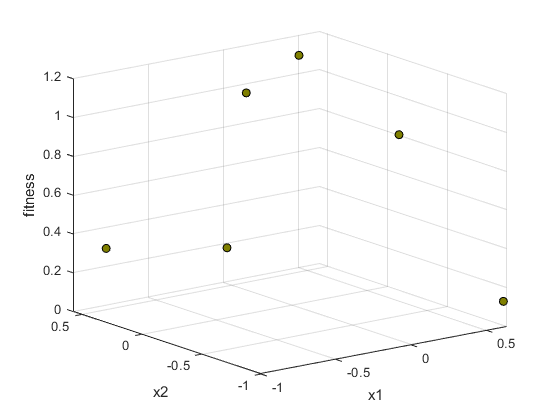

% seed has to be set true only once here to generate the tabular report for
% both X1 and X2. From generation 3 and onwards, the seed will always be
% false
[X2]= run_genetic_algo(X1, U, L, J, n_feature, N, 1);

## Calculate Generation 2

DataTable = 6×6 table
    candidate_index       x1           x2          fit      fractional_fit    cumulative_prob
    _______________    _________    _________    _______    ______________    _______________

           1            -0.86667      0.56863    0.11728       0.019243          0.019243    
           2             0.57647     0.019608     1.0476        0.17189           0.19114    
           3           0.0039216     -0.18431     1.2712        0.20858           0.39971    
           4             0.05098    0.0039216     1.4544        0.23863           0.63834    
           5            -0.18431          0.2     1.0506        0.17238           0.81072    
           6              0.3594       0.3906     1.1536        0.18928                 1    


ResultTable = 1×2 table
    fitness_sum    fitness_average
    ___________    _______________

      6.0948           1.0158     


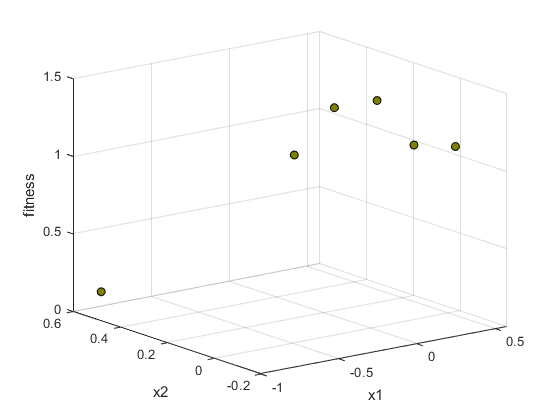

X3 = run_genetic_algo(X2, U, L, J, n_feature, N, 0);

## Calculate Generation 3

DataTable = 6×6 table
    candidate_index       x1           x2         fit      fractional_fit    cumulative_prob
    _______________    _________    _________    ______    ______________    _______________

           1             0.07451    0.0039216    1.4107       0.17987            0.17987    
           2           0.0039216      0.19216    1.2741       0.16245            0.34232    
           3            -0.18431     -0.17647    1.0421       0.13287            0.47519    
           4            0.043137    0.0039216    1.4666       0.18699            0.66218    
           5             0.31765      0.38824    1.1951       0.15238            0.81456    
           6             0.05098    0.0039216    1.4544       0.18544                  1    


ResultTable = 1×2 table
    fitness_sum    fitness_average
    ___________    _______________

       7.843           1.3072     


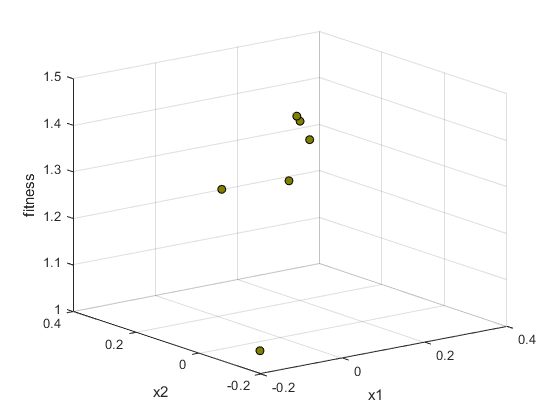

X4 = run_genetic_algo(X3, U, L, J, n_feature, N, 0);

## Calculate Generation 4

DataTable = 6×6 table
    candidate_index       x1           x2         fit      fractional_fit    cumulative_prob
    _______________    _________    _________    ______    ______________    _______________

           1            0.043137    0.0039216    1.4666       0.17803            0.17803    
           2             0.07451    0.0039216    1.4107       0.17125            0.34928    
           3             0.05098      0.19216    1.2291        0.1492            0.49849    
           4           0.0039216    0.0039216    1.4994       0.18202            0.68051    
           5             0.31765     -0.17647    1.1653       0.14146            0.82197    
           6            0.043137    0.0039216    1.4666       0.17803                  1    


ResultTable = 1×2 table
    fitness_sum    fitness_average
    ___________    _______________

      8.2377           1.3729     


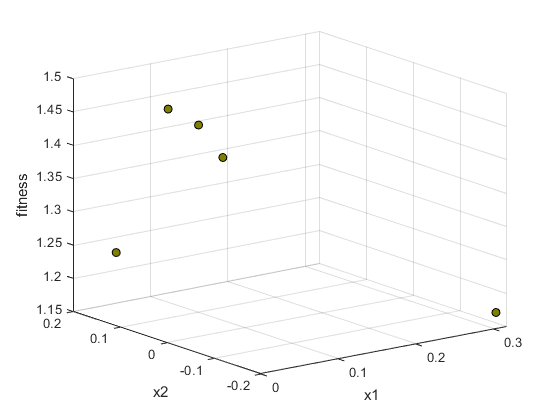

X5 = run_genetic_algo(X4, U, L, J, n_feature, N, 0);

## Calculate Generation 5

DataTable = 6×6 table
    candidate_index       x1           x2         fit      fractional_fit    cumulative_prob
    _______________    _________    _________    ______    ______________    _______________

           1           0.0039216    0.0039216    1.4994       0.17624            0.17624    
           2             0.07451    0.0039216    1.4107       0.16581            0.34205    
           3            0.043137    0.0039216    1.4666       0.17238            0.51442    
           4             0.31765    0.0039216    1.3945        0.1639            0.67832    
           5            0.043137     -0.17647    1.2374       0.14544            0.82376    
           6           0.0039216    0.0039216    1.4994       0.17624                  1    


ResultTable = 1×2 table
    fitness_sum    fitness_average
    ___________    _______________

       8.508            1.418     


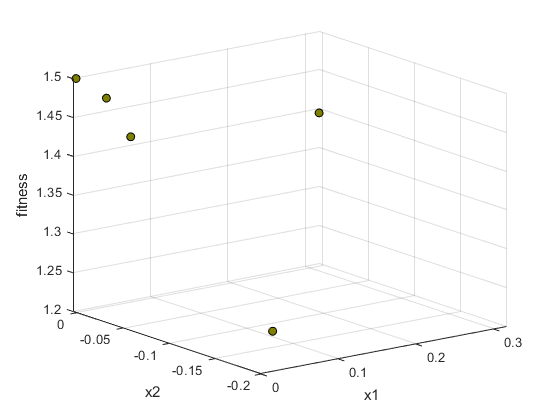

X6 = run_genetic_algo(X5, U, L, J, n_feature, N, 0);